clc;
clear all;
close all;

filename ='Drone_data_large.csv'; data = readtable(filename); data=data{:,:}; F450 = data(:,1); M100=data(:,2); P4P=data(:,3); Walkera=data(:,4);

F450 = F450(1:1810); M100 = M100([6:186,197:377,388:568,579:759,770:950,961:1141,1152:1332,1343:1523,1534:1714,1725:1905]); P4P = P4P([6:186,197:377,388:568,579:759,770:950,961:1141,1152:1332,1343:1523,1534:1714,1725:1905]); Walkera = Walkera([6:186,197:377,388:568,579:759,770:950,961:1141,1152:1332,1343:1523,1534:1714,1725:1905]);

F450 = reshape(F450, [], 10); M100 = reshape(M100, [], 10); P4P = reshape(P4P, [], 10); Walkera = reshape(Walkera, [], 10);

N=181; NumObj=10; NumTestObj=ceil(0.3*NumObj); NumTrainObj=ceil(0.7*NumObj);

filename ='All_Drone.csv';
data = readtable(filename);
data=data{:,:};
F450 = data(:,1);
M100=data(:,2);
P4P=data(:,3);
Walkera=data(:,4);
Y600=data(:,10);

F450 = F450(1:16290);
newM100=[];
newP4P=[];
newWalkera=[];
newY600=[];
x=6;
for i=1:90
    newM100 = [newM100;M100(x:x+180)];
    newP4P = [newP4P;P4P(x:x+180)];
    newWalkera = [newWalkera;Walkera(x:x+180)];
    newY600 = [newY600; Y600(x:x+180)];
    x=x+191;
end

% M100 = M100([6:186,197:377,388:568,579:759,770:950,961:1141,1152:1332,1343:1523,1534:1714,1725:1905]);
% P4P = P4P([6:186,197:377,388:568,579:759,770:950,961:1141,1152:1332,1343:1523,1534:1714,1725:1905]);
% Walkera = Walkera([6:186,197:377,388:568,579:759,770:950,961:1141,1152:1332,1343:1523,1534:1714,1725:1905]);


F450 = reshape(F450, [], 90);
M100 = reshape(newM100, [], 90);
P4P = reshape(newP4P, [], 90);
Walkera = reshape(newWalkera, [], 90);
Y600 = reshape(newY600,[], 90);

N=181;
NumObj=90;
NumTestObj=ceil(0.3*NumObj);
NumTrainObj=ceil(0.7*NumObj);

Ffeat=[];
Mfeat=[];
Pfeat=[];
Wfeat=[];
Yfeat=[];
for i=1:NumObj
    sigf = std(F450(:,i));  muf = mean(F450(:,i)); 
    sigm = std(M100(:,i));  mum = mean(M100(:,i));
    sigp = std(P4P(:,i)); mup = mean(P4P(:,i));
    sigw = std(Walkera(:,i)); muw = mean(Walkera(:,i));
    sigy = std(Y600(:,i)); muy = mean(Y600(:,i));
    fstd = (F450(:,i) - muf) / sigf; 
    mstd = (M100(:,i) - mum) / sigm;
    pstd = (P4P(:,i) - mup) / sigp;
    wstd = (Walkera(:,i) - muw) / sigw;
    ystd = (Y600(:,i) - muy) / sigy;
    emdF450=emd(fstd,'Interpolation','pchip','Display',1,"MaxNumIMF",4);
    emdM100=emd(mstd,'Interpolation','pchip','Display',1,"MaxNumIMF",4);
    emdP4P=emd(pstd,'Interpolation','pchip','Display',1,"MaxNumIMF",4);
    emdWalkera=emd(wstd,'Interpolation','pchip','Display',1,"MaxNumIMF",4);
    emdY600=emd(ystd,'Interpolation','pchip','Display',1,"MaxNumIMF",4);
    memdF450=mean(emdF450);sigemdF450=std(emdF450);maxemdF50=max(emdF450);minemdF450=min(emdF450);
    memdM100=mean(emdM100);sigemdM100=std(emdM100);maxemdM100=max(emdM100);minemdM100=min(emdM100);
    memdP4P=mean(emdP4P);sigemdP4P=std(emdP4P);maxemdP4P=max(emdP4P);minemdP4P=min(emdP4P);
    memdWalkera=mean(emdWalkera);sigemdWalkera=std(emdWalkera);maxemdWalkera=max(emdWalkera);minemdWalkera=min(emdWalkera);
    memdY600=mean(emdY600);sigemdY600=std(emdY600);maxemdY600=max(emdY600);minemdY600=min(emdY600);
    Ffeat =[Ffeat; [muf memdF450 sigf sigemdF450 max(F450(:,i)) maxemdF50 min(F450(:,i)) minemdF450]];
    Mfeat =[Mfeat; [mum memdM100 sigm sigemdM100 max(M100(:,i)) maxemdM100 min(M100(:,i)) minemdM100]];
    Pfeat =[Pfeat; [mup memdP4P sigp sigemdP4P max(P4P(:,i)) maxemdP4P min(P4P(:,i)) minemdP4P]];
    Wfeat =[Wfeat; [muw memdWalkera sigw sigemdWalkera max(Walkera(:,i)) maxemdWalkera min(Walkera(:,i)) minemdWalkera]];
    Yfeat =[Yfeat; [muy memdY600 sigy sigemdY600 max(Y600(:,i)) maxemdY600 min(Y600(:,i)) minemdY600]];
end

Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019631   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18545   |  SiftMaxRelativeTolerance
      3      |        2     |     0.056177   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11447   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.083722   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12073   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10967   |  SiftMaxRelativeTolerance
      4      |        2     |     0.038195   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.046022   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13932   |  SiftMaxRelativeTolerance
      3      |        2     |      0.18668   |  SiftMaxRelativeTolerance
      4      |        2     |     0.035979   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040176   |  SiftMaxRelativeTolerance
      2      |        2     |      0.04689   |  SiftMaxRelativeTolerance
      3      |        2     |     0.045851   |  SiftMaxRelativeTolerance
      4      |        2     |    0.0096954   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032608   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064984   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13765   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16373   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033877   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10795   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17158   |  SiftMaxRelativeTolerance
      4      |        3     |     0.049008   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02009   |  SiftMaxRelativeTolerance
      2      |        3     |     0.067731   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11624   |  SiftMaxRelativeTolerance
      4      |        2     |      0.02616   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.055903   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1002   |  SiftMaxRelativeTolerance
      3      |        2     |     0.081276   |  SiftMaxRelativeTolerance
      4      |        1     |      0.17634   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02836   |  SiftMaxRelativeTolerance
      2      |        2     |     0.080264   |  SiftMaxRelativeTolerance
      3      |        2     |      0.09209   |  SiftMaxRelativeTolerance
      4      |        2     |     0.071377   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.05578   |  SiftMaxRelativeTolerance
      2      |        2     |     0.040201   |  SiftMaxRelativeTolerance
      3      |        2     |     0.061821   |  SiftMaxRelativeTolerance
      4      |        2     |     0.062898   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.011034   |  SiftMaxRelativeTolerance
      2      |        3     |     0.044065   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077757   |  SiftMaxRelativeTolerance
      4      |        3     |     0.046346   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038148   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10476   |  SiftMaxRelativeTolerance
      3      |        2     |      0.04194   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091631   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.063144   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060954   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052648   |  SiftMaxRelativeTolerance
      4      |        2     |     0.047273   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038555   |  SiftMaxRelativeTolerance
      2      |        2     |     0.049519   |  SiftMaxRelativeTolerance
      3      |        2     |     0.093609   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11737   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057257   |  SiftMaxRelativeTolerance
      2      |        2     |     0.050864   |  SiftMaxRelativeTolerance
      3      |        2     |     0.047745   |  SiftMaxRelativeTolerance
      4      |        2     |     0.057374   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030508   |  SiftMaxRelativeTolerance
      2      |        2     |     0.025333   |  SiftMaxRelativeTolerance
      3      |        2     |     0.099646   |  SiftMaxRelativeTolerance
      4      |        3     |     0.041357   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031043   |  SiftMaxRelativeTolerance
      2      |        2     |     0.069147   |  SiftMaxRelativeTolerance
      3      |        3     |      0.01702   |  SiftMaxRelativeTolerance
      4      |        3     |     0.071649   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02471   |  SiftMaxRelativeTolerance
      2      |        2     |      0.19504   |  SiftMaxRelativeTolerance
      3      |        3     |     0.034321   |  SiftMaxRelativeTolerance
      4      |        1     |      0.19604   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032787   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064627   |  SiftMaxRelativeTolerance
      3      |        2     |     0.050733   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16828   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.058029   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06051   |  SiftMaxRelativeTolerance
      3      |        2     |     0.033786   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1755   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03118   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12978   |  SiftMaxRelativeTolerance
      3      |        2     |     0.036561   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10338   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.068581   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15001   |  SiftMaxRelativeTolerance
      3      |        2     |     0.055414   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11573   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.083322   |  SiftMaxRelativeTolerance
      2      |        2     |     0.074033   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069021   |  SiftMaxRelativeTolerance
      4      |        1     |     0.069234   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.090256   |  SiftMaxRelativeTolerance
      2      |        2     |     0.081479   |  SiftMaxRelativeTolerance
      3      |        3     |     0.081813   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14113   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032845   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065978   |  SiftMaxRelativeTolerance
      3      |        3     |     0.020338   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16981   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.037791   |  SiftMaxRelativeTolerance
      2      |        2     |     0.030974   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066991   |  SiftMaxRelativeTolerance
      4      |        2     |     0.066785   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.069959   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1277   |  SiftMaxRelativeTolerance
      3      |        2     |     0.038818   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13595   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033637   |  SiftMaxRelativeTolerance
      2      |        2     |     0.078837   |  SiftMaxRelativeTolerance
      3      |        2     |     0.051968   |  SiftMaxRelativeTolerance
      4      |        3     |     0.011214   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033458   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065725   |  SiftMaxRelativeTolerance
      3      |        3     |     0.065865   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18378   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.047329   |  SiftMaxRelativeTolerance
      2      |        2     |     0.046693   |  SiftMaxRelativeTolerance
      3      |        2     |     0.083619   |  SiftMaxRelativeTolerance
      4      |        3     |      0.12972   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.061635   |  SiftMaxRelativeTolerance
      2      |        2     |     0.049479   |  SiftMaxRelativeTolerance
      3      |        2     |     0.049136   |  SiftMaxRelativeTolerance
      4      |        2     |     0.027913   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038508   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1305   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16841   |  SiftMaxRelativeTolerance
      4      |        3     |     0.029433   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.072051   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059004   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10658   |  SiftMaxRelativeTolerance
      4      |        2     |     0.017541   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023315   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1155   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17379   |  SiftMaxRelativeTolerance
      4      |        1     |      0.11845   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.045039   |  SiftMaxRelativeTolerance
      2      |        3     |     0.056622   |  SiftMaxRelativeTolerance
      3      |        2     |     0.039139   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1802   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023033   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059222   |  SiftMaxRelativeTolerance
      3      |        2     |      0.18787   |  SiftMaxRelativeTolerance
      4      |        2     |     0.059154   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024602   |  SiftMaxRelativeTolerance
      2      |        3     |     0.036519   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17617   |  SiftMaxRelativeTolerance
      4      |        2     |     0.088791   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.067813   |  SiftMaxRelativeTolerance
      2      |        2     |     0.069154   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1209   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076079   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.054982   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16781   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15414   |  SiftMaxRelativeTolerance
      4      |        4     |     0.038845   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.064539   |  SiftMaxRelativeTolerance
      2      |        2     |     0.043558   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15237   |  SiftMaxRelativeTolerance
      4      |        2     |     0.048221   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023074   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10581   |  SiftMaxRelativeTolerance
      3      |        2     |     0.090636   |  SiftMaxRelativeTolerance
      4      |        2     |     0.023577   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.069107   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12786   |  SiftMaxRelativeTolerance
      3      |        2     |     0.082774   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17658   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038395   |  SiftMaxRelativeTolerance
      2      |        2     |     0.044015   |  SiftMaxRelativeTolerance
      3      |        2     |     0.048681   |  SiftMaxRelativeTolerance
      4      |        2     |     0.017093   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050518   |  SiftMaxRelativeTolerance
      2      |        2     |     0.040861   |  SiftMaxRelativeTolerance
      3      |        2     |      0.04122   |  SiftMaxRelativeTolerance
      4      |        1     |      0.10834   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.089859   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10504   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078088   |  SiftMaxRelativeTolerance
      4      |        1     |        0.154   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049376   |  SiftMaxRelativeTolerance
      2      |        2     |     0.056486   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15635   |  SiftMaxRelativeTolerance
      4      |        2     |        0.122   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.055557   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062747   |  SiftMaxRelativeTolerance
      3      |        2     |      0.18606   |  SiftMaxRelativeTolerance
      4      |        2     |     0.038415   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.14211   |  SiftMaxRelativeTolerance
      2      |        2     |     0.088635   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078575   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12755   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031194   |  SiftMaxRelativeTolerance
      2      |        2     |     0.073695   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16499   |  SiftMaxRelativeTolerance
      4      |        2     |      0.08355   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.08422   |  SiftMaxRelativeTolerance
      2      |        2     |     0.022797   |  SiftMaxRelativeTolerance
      3      |        3     |      0.12575   |  SiftMaxRelativeTolerance
      4      |        3     |      0.14951   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.044302   |  SiftMaxRelativeTolerance
      2      |        2     |     0.022536   |  SiftMaxRelativeTolerance
      3      |        2     |     0.093007   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11504   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031937   |  SiftMaxRelativeTolerance
      2      |        3     |      0.01642   |  SiftMaxRelativeTolerance
      3      |        2     |     0.081068   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073188   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.056066   |  SiftMaxRelativeTolerance
      2      |        2     |      0.14932   |  SiftMaxRelativeTolerance
      3      |        2     |     0.010247   |  SiftMaxRelativeTolerance
      4      |        3     |     0.032503   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.053683   |  SiftMaxRelativeTolerance
      2      |        2     |     0.049517   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1614   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17899   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.048493   |  SiftMaxRelativeTolerance
      2      |        3     |     0.042863   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076416   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16133   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021526   |  SiftMaxRelativeTolerance
      2      |        2     |     0.042069   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076493   |  SiftMaxRelativeTolerance
      4      |        2     |     0.013718   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030723   |  SiftMaxRelativeTolerance
      2      |        3     |     0.070784   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068467   |  SiftMaxRelativeTolerance
      4      |        3     |      0.19878   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026598   |  SiftMaxRelativeTolerance
      2      |        2     |     0.079955   |  SiftMaxRelativeTolerance
      3      |        2     |      0.02293   |  SiftMaxRelativeTolerance
      4      |        2     |     0.012422   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.059391   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13484   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13099   |  SiftMaxRelativeTolerance
      4      |        2     |     0.041159   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029215   |  SiftMaxRelativeTolerance
      2      |        3     |      0.17415   |  SiftMaxRelativeTolerance
      3      |        2     |      0.18058   |  SiftMaxRelativeTolerance
      4      |        2     |      0.09229   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02318   |  SiftMaxRelativeTolerance
      2      |        2     |     0.032865   |  SiftMaxRelativeTolerance
      3      |        2     |     0.035961   |  SiftMaxRelativeTolerance
      4      |        2     |     0.056348   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024286   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13048   |  SiftMaxRelativeTolerance
      3      |        3     |     0.048338   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12872   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04982   |  SiftMaxRelativeTolerance
      2      |        2     |     0.047929   |  SiftMaxRelativeTolerance
      3      |        3     |      0.14997   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18689   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019616   |  SiftMaxRelativeTolerance
      2      |        2     |     0.072851   |  SiftMaxRelativeTolerance
      3      |        2     |     0.058331   |  SiftMaxRelativeTolerance
      4      |        2     |     0.078284   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0282   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10325   |  SiftMaxRelativeTolerance
      3      |        2     |     0.034242   |  SiftMaxRelativeTolerance
      4      |        2     |     0.050454   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019078   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18668   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14243   |  SiftMaxRelativeTolerance
      4      |        5     |     0.052424   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.044615   |  SiftMaxRelativeTolerance
      2      |        3     |      0.16207   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15793   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13714   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.060317   |  SiftMaxRelativeTolerance
      2      |        2     |      0.03886   |  SiftMaxRelativeTolerance
      3      |        2     |     0.032475   |  SiftMaxRelativeTolerance
      4      |        3     |      0.12122   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027673   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067745   |  SiftMaxRelativeTolerance
      3      |        2     |     0.095972   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1921   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.07783   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067647   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13466   |  SiftMaxRelativeTolerance
      4      |        2     |     0.044806   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.045035   |  SiftMaxRelativeTolerance
      2      |        2     |     0.045491   |  SiftMaxRelativeTolerance
      3      |        2     |     0.053395   |  SiftMaxRelativeTolerance
      4      |        2     |     0.073147   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050669   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066013   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10841   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16113   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029376   |  SiftMaxRelativeTolerance
      2      |        3     |     0.020236   |  SiftMaxRelativeTolerance
      3      |        2     |     0.060303   |  SiftMaxRelativeTolerance
      4      |        3     |      0.13094   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.014701   |  SiftMaxRelativeTolerance
      2      |        2     |       0.0644   |  SiftMaxRelativeTolerance
      3      |        2     |     0.076354   |  SiftMaxRelativeTolerance
      4      |        2     |     0.054712   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043104   |  SiftMaxRelativeTolerance
      2      |        2     |     0.035199   |  SiftMaxRelativeTolerance
      3      |        3     |     0.065033   |  SiftMaxRelativeTolerance
      4      |        4     |      0.19089   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029505   |  SiftMaxRelativeTolerance
      2      |        2     |     0.044564   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0505   |  SiftMaxRelativeTolerance
      4      |        3     |     0.085349   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032313   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15846   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11737   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18351   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.046563   |  SiftMaxRelativeTolerance
      2      |        2     |     0.031323   |  SiftMaxRelativeTolerance
      3      |        3     |     0.031764   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13225   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030539   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066703   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052456   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10035   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.095346   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059191   |  SiftMaxRelativeTolerance
      3      |        2     |     0.058662   |  SiftMaxRelativeTolerance
      4      |        3     |     0.065782   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024433   |  SiftMaxRelativeTolerance
      2      |        2     |     0.073065   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075665   |  SiftMaxRelativeTolerance
      4      |        2     |     0.039309   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.080494   |  SiftMaxRelativeTolerance
      2      |        2     |      0.19523   |  SiftMaxRelativeTolerance
      3      |        3     |     0.049327   |  SiftMaxRelativeTolerance
      4      |        3     |    0.0072219   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036887   |  SiftMaxRelativeTolerance
      2      |        2     |     0.080873   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12934   |  SiftMaxRelativeTolerance
      4      |        3     |      0.12078   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038635   |  SiftMaxRelativeTolerance
      2      |        2     |     0.074429   |  SiftMaxRelativeTolerance
      3      |        2     |      0.01698   |  SiftMaxRelativeTolerance
      4      |        3     |       0.1812   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043731   |  SiftMaxRelativeTolerance
      2      |        2     |      0.03854   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1644   |  SiftMaxRelativeTolerance
      4      |        2     |      0.05177   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030957   |  SiftMaxRelativeTolerance
      2      |        2     |     0.022649   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077747   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18711   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024794   |  SiftMaxRelativeTolerance
      2      |        2     |     0.055959   |  SiftMaxRelativeTolerance
      3      |        2     |     0.049867   |  SiftMaxRelativeTolerance
      4      |        3     |     0.029703   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.10092   |  SiftMaxRelativeTolerance
      2      |        2     |     0.076611   |  SiftMaxRelativeTolerance
      3      |        2     |      0.18655   |  SiftMaxRelativeTolerance
      4      |        1     |        0.114   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038832   |  SiftMaxRelativeTolerance
      2      |        2     |     0.058654   |  SiftMaxRelativeTolerance
      3      |        3     |      0.05832   |  SiftMaxRelativeTolerance
      4      |        2     |     0.028137   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03431   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12288   |  SiftMaxRelativeTolerance
      3      |        3     |       0.0155   |  SiftMaxRelativeTolerance
      4      |        2     |     0.052842   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04263   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036158   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11626   |  SiftMaxRelativeTolerance
      4      |        3     |     0.026322   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043222   |  SiftMaxRelativeTolerance
      2      |        2     |     0.042179   |  SiftMaxRelativeTolerance
      3      |        3     |     0.033164   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15878   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04162   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10355   |  SiftMaxRelativeTolerance
      3      |        2     |     0.036806   |  SiftMaxRelativeTolerance
      4      |        1     |     0.071769   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036976   |  SiftMaxRelativeTolerance
      2      |        2     |     0.023381   |  SiftMaxRelativeTolerance
      3      |        2     |     0.083367   |  SiftMaxRelativeTolerance
      4      |        2     |     0.063712   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.037128   |  SiftMaxRelativeTolerance
      2      |        3     |     0.065581   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15727   |  SiftMaxRelativeTolerance
      4      |        1     |      0.19218   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022231   |  SiftMaxRelativeTolerance
      2      |        2     |      0.19322   |  SiftMaxRelativeTolerance
      3      |        3     |     0.042817   |  SiftMaxRelativeTolerance
      4      |        2     |     0.052315   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.054414   |  SiftMaxRelativeTolerance
      2      |        3     |      0.11642   |  SiftMaxRelativeTolerance
      3      |        3     |      0.18991   |  SiftMaxRelativeTolerance
      4      |        3     |     0.051521   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.070602   |  SiftMaxRelativeTolerance
      2      |        2     |      0.05925   |  SiftMaxRelativeTolerance
      3      |        4     |     0.058249   |  SiftMaxRelativeTolerance
      4      |        3     |     0.077709   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022796   |  SiftMaxRelativeTolerance
      2      |        3     |     0.065427   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077732   |  SiftMaxRelativeTolerance
      4      |        4     |      0.17029   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029233   |  SiftMaxRelativeTolerance
      2      |        3     |     0.019886   |  SiftMaxRelativeTolerance
      3      |        2     |     0.093094   |  SiftMaxRelativeTolerance
      4      |        2     |     0.056251   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02584   |  SiftMaxRelativeTolerance
      2      |        2     |     0.076189   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10709   |  SiftMaxRelativeTolerance
      4      |        3     |     0.028512   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.084453   |  SiftMaxRelativeTolerance
      2      |        2     |     0.095268   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16687   |  SiftMaxRelativeTolerance
      4      |        3     |     0.057799   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022835   |  SiftMaxRelativeTolerance
      2      |        2     |     0.039333   |  SiftMaxRelativeTolerance
      3      |        2     |      0.07688   |  SiftMaxRelativeTolerance
      4      |        3     |     0.047548   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.028655   |  SiftMaxRelativeTolerance
      2      |        2     |     0.051082   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10818   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1419   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.053734   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13078   |  SiftMaxRelativeTolerance
      3      |        3     |     0.044136   |  SiftMaxRelativeTolerance
      4      |        3     |      0.17984   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039013   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036502   |  SiftMaxRelativeTolerance
      3      |        3     |     0.030506   |  SiftMaxRelativeTolerance
      4      |        3     |     0.028487   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.14943   |  SiftMaxRelativeTolerance
      2      |        2     |     0.080236   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1678   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10297   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029805   |  SiftMaxRelativeTolerance
      2      |        2     |     0.056433   |  SiftMaxRelativeTolerance
      3      |        2     |     0.081003   |  SiftMaxRelativeTolerance
      4      |        1     |       0.1755   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.051128   |  SiftMaxRelativeTolerance
      2      |        2     |     0.026835   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17733   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19081   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034004   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10711   |  SiftMaxRelativeTolerance
      3      |        3     |     0.027019   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17869   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049305   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059313   |  SiftMaxRelativeTolerance
      3      |        3     |     0.031471   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18329   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.11672   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18667   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10879   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11001   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022353   |  SiftMaxRelativeTolerance
      2      |        2     |     0.058069   |  SiftMaxRelativeTolerance
      3      |        5     |    0.0088076   |  SiftMaxRelativeTolerance
      4      |        3     |     0.083475   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040508   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10129   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15796   |  SiftMaxRelativeTolerance
      4      |        3     |     0.090905   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033641   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13245   |  SiftMaxRelativeTolerance
      3      |        3     |      0.12184   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15436   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031889   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10279   |  SiftMaxRelativeTolerance
      3      |        2     |     0.078688   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10687   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.12044   |  SiftMaxRelativeTolerance
      2      |        2     |     0.072137   |  SiftMaxRelativeTolerance
      3      |        3     |     0.068048   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075819   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.067959   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1437   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10981   |  SiftMaxRelativeTolerance
      4      |        1     |      0.05781   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038198   |  SiftMaxRelativeTolerance
      2      |        2     |      0.14038   |  SiftMaxRelativeTolerance
      3      |        4     |     0.025611   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10394   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.086786   |  SiftMaxRelativeTolerance
      2      |        2     |     0.074211   |  SiftMaxRelativeTolerance
      3      |        3     |     0.047629   |  SiftMaxRelativeTolerance
      4      |        1     |      0.13854   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023912   |  SiftMaxRelativeTolerance
      2      |        3     |     0.025915   |  SiftMaxRelativeTolerance
      3      |        2     |     0.057341   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094056   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.065747   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11869   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1674   |  SiftMaxRelativeTolerance
      4      |        2     |     0.097909   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039584   |  SiftMaxRelativeTolerance
      2      |        3     |     0.044752   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14818   |  SiftMaxRelativeTolerance
      4      |        3     |      0.03222   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032162   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1076   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052078   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099512   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.060824   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060056   |  SiftMaxRelativeTolerance
      3      |        3     |      0.14066   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16121   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057325   |  SiftMaxRelativeTolerance
      2      |        2     |     0.094116   |  SiftMaxRelativeTolerance
      3      |        2     |     0.097972   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1205   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.07393   |  SiftMaxRelativeTolerance
      2      |        2     |     0.081662   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052601   |  SiftMaxRelativeTolerance
      4      |        3     |      0.08541   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030281   |  SiftMaxRelativeTolerance
      2      |        2     |      0.14743   |  SiftMaxRelativeTolerance
      3      |        3     |       0.0664   |  SiftMaxRelativeTolerance
      4      |        3     |     0.080476   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.041608   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13916   |  SiftMaxRelativeTolerance
      3      |        3     |     0.025764   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11865   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.053242   |  SiftMaxRelativeTolerance
      2      |        2     |     0.051677   |  SiftMaxRelativeTolerance
      3      |        2     |      0.18751   |  SiftMaxRelativeTolerance
      4      |        1     |       0.1604   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033807   |  SiftMaxRelativeTolerance
      2      |        2     |     0.046197   |  SiftMaxRelativeTolerance
      3      |        2     |     0.094363   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19218   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.074641   |  SiftMaxRelativeTolerance
      2      |        2     |     0.093313   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077928   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12823   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.063123   |  SiftMaxRelativeTolerance
      2      |        2     |     0.089702   |  SiftMaxRelativeTolerance
      3      |        2     |      0.09481   |  SiftMaxRelativeTolerance
      4      |        2     |     0.038324   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030217   |  SiftMaxRelativeTolerance
      2      |        2     |     0.076511   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11484   |  SiftMaxRelativeTolerance
      4      |        3     |     0.040415   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.051809   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084248   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10473   |  SiftMaxRelativeTolerance
      4      |        1     |      0.16731   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.042932   |  SiftMaxRelativeTolerance
      2      |        2     |      0.08956   |  SiftMaxRelativeTolerance
      3      |        3     |     0.027277   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10661   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024776   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10207   |  SiftMaxRelativeTolerance
      3      |        2     |     0.080426   |  SiftMaxRelativeTolerance
      4      |        3     |     0.038418   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.020626   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10553   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10974   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12864   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.037133   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13712   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13311   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18261   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.018639   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12191   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12901   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15617   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027113   |  SiftMaxRelativeTolerance
      2      |        2     |     0.043948   |  SiftMaxRelativeTolerance
      3      |        2     |     0.026026   |  SiftMaxRelativeTolerance
      4      |        4     |      0.12031   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030135   |  SiftMaxRelativeTolerance
      2      |        2     |     0.058258   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11606   |  SiftMaxRelativeTolerance
      4      |        2     |     0.024165   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.044064   |  SiftMaxRelativeTolerance
      2      |        2     |     0.038046   |  SiftMaxRelativeTolerance
      3      |        2     |     0.092492   |  SiftMaxRelativeTolerance
      4      |        2     |     0.025532   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039734   |  SiftMaxRelativeTolerance
      2      |        2     |     0.033279   |  SiftMaxRelativeTolerance
      3      |        2     |     0.087351   |  SiftMaxRelativeTolerance
      4      |        1     |      0.16538   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.042918   |  SiftMaxRelativeTolerance
      2      |        2     |     0.047088   |  SiftMaxRelativeTolerance
      3      |        3     |     0.068187   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14017   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.015448   |  SiftMaxRelativeTolerance
      2      |        3     |     0.019413   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1124   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13754   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022755   |  SiftMaxRelativeTolerance
      2      |        2     |     0.035112   |  SiftMaxRelativeTolerance
      3      |        3     |       0.0402   |  SiftMaxRelativeTolerance
      4      |        2     |     0.044676   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.056413   |  SiftMaxRelativeTolerance
      2      |        2     |     0.032418   |  SiftMaxRelativeTolerance
      3      |        3     |     0.035436   |  SiftMaxRelativeTolerance
      4      |        1     |      0.13013   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019427   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066634   |  SiftMaxRelativeTolerance
      3      |        2     |      0.19007   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1126   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.070962   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11272   |  SiftMaxRelativeTolerance
      3      |        3     |     0.067744   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095442   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.042042   |  SiftMaxRelativeTolerance
      2      |        2     |     0.090018   |  SiftMaxRelativeTolerance
      3      |        2     |     0.051817   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15918   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.093926   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036952   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11081   |  SiftMaxRelativeTolerance
      4      |        2     |     0.049183   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027801   |  SiftMaxRelativeTolerance
      2      |        2     |      0.19635   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14046   |  SiftMaxRelativeTolerance
      4      |        3     |     0.047306   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030648   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066068   |  SiftMaxRelativeTolerance
      3      |        2     |     0.062607   |  SiftMaxRelativeTolerance
      4      |        2     |      0.05882   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.068372   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1862   |  SiftMaxRelativeTolerance
      3      |        2     |     0.046296   |  SiftMaxRelativeTolerance
      4      |        2     |    0.0066432   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.060551   |  SiftMaxRelativeTolerance
      2      |        2     |     0.094694   |  SiftMaxRelativeTolerance
      3      |        2     |     0.017947   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13461   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034905   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13105   |  SiftMaxRelativeTolerance
      3      |        3     |     0.072162   |  SiftMaxRelativeTolerance
      4      |        2     |     0.045222   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.17864   |  SiftMaxRelativeTolerance
      2      |        2     |    0.0096275   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067075   |  SiftMaxRelativeTolerance
      4      |        3     |      0.07478   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02641   |  SiftMaxRelativeTolerance
      2      |        2     |     0.058752   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13044   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13876   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057567   |  SiftMaxRelativeTolerance
      2      |        2     |     0.099212   |  SiftMaxRelativeTolerance
      3      |        2     |     0.027319   |  SiftMaxRelativeTolerance
      4      |        2     |     0.084632   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027537   |  SiftMaxRelativeTolerance
      2      |        2     |     0.056601   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14568   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076985   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043123   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10193   |  SiftMaxRelativeTolerance
      3      |        2     |     0.090682   |  SiftMaxRelativeTolerance
      4      |        4     |     0.041337   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03648   |  SiftMaxRelativeTolerance
      2      |        2     |     0.044718   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15017   |  SiftMaxRelativeTolerance
      4      |        2     |     0.051419   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024601   |  SiftMaxRelativeTolerance
      2      |        2     |      0.14563   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073159   |  SiftMaxRelativeTolerance
      4      |        4     |       0.1051   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029984   |  SiftMaxRelativeTolerance
      2      |        2     |     0.079433   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10694   |  SiftMaxRelativeTolerance
      4      |        2     |    0.0082093   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034566   |  SiftMaxRelativeTolerance
      2      |        2     |     0.028633   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10251   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098698   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036054   |  SiftMaxRelativeTolerance
      2      |        2     |     0.047418   |  SiftMaxRelativeTolerance
      3      |        2     |     0.029993   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13886   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.086979   |  SiftMaxRelativeTolerance
      2      |        2     |      0.01899   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10268   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11358   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02501   |  SiftMaxRelativeTolerance
      2      |        2     |     0.089213   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11129   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14654   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023085   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10373   |  SiftMaxRelativeTolerance
      3      |        3     |     0.016743   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16966   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.059622   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063307   |  SiftMaxRelativeTolerance
      3      |        3     |     0.022765   |  SiftMaxRelativeTolerance
      4      |        2     |     0.066918   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034435   |  SiftMaxRelativeTolerance
      2      |        2     |     0.035101   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17652   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072892   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.028947   |  SiftMaxRelativeTolerance
      2      |        2     |     0.078397   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11593   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17661   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057252   |  SiftMaxRelativeTolerance
      2      |        2     |     0.053359   |  SiftMaxRelativeTolerance
      3      |        2     |     0.038965   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10005   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033125   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10738   |  SiftMaxRelativeTolerance
      3      |        2     |     0.096799   |  SiftMaxRelativeTolerance
      4      |        3     |     0.062066   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034788   |  SiftMaxRelativeTolerance
      2      |        2     |     0.038534   |  SiftMaxRelativeTolerance
      3      |        2     |     0.029299   |  SiftMaxRelativeTolerance
      4      |        3     |      0.15956   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.17618   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12697   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13723   |  SiftMaxRelativeTolerance
      4      |        2     |     0.068823   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03086   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12318   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10677   |  SiftMaxRelativeTolerance
      4      |        2     |     0.089898   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04899   |  SiftMaxRelativeTolerance
      2      |        2     |     0.056982   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12852   |  SiftMaxRelativeTolerance
      4      |        3     |      0.15561   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043208   |  SiftMaxRelativeTolerance
      2      |        3     |     0.026279   |  SiftMaxRelativeTolerance
      3      |        2     |     0.058163   |  SiftMaxRelativeTolerance
      4      |        2     |      0.08456   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026327   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10612   |  SiftMaxRelativeTolerance
      3      |        2     |     0.035162   |  SiftMaxRelativeTolerance
      4      |        3     |     0.071468   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049302   |  SiftMaxRelativeTolerance
      2      |        2     |     0.096801   |  SiftMaxRelativeTolerance
      3      |        2     |     0.053472   |  SiftMaxRelativeTolerance
      4      |        2     |     0.028984   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.088288   |  SiftMaxRelativeTolerance
      2      |        2     |     0.089063   |  SiftMaxRelativeTolerance
      3      |        3     |     0.015628   |  SiftMaxRelativeTolerance
      4      |        1     |      0.18804   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.013909   |  SiftMaxRelativeTolerance
      2      |        2     |     0.034259   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11572   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16084   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.052861   |  SiftMaxRelativeTolerance
      2      |        3     |     0.044298   |  SiftMaxRelativeTolerance
      3      |        2     |     0.055968   |  SiftMaxRelativeTolerance
      4      |        2     |      0.04502   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.051331   |  SiftMaxRelativeTolerance
      2      |        3     |      0.12026   |  SiftMaxRelativeTolerance
      3      |        2     |     0.089568   |  SiftMaxRelativeTolerance
      4      |        3     |     0.076657   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.01918   |  SiftMaxRelativeTolerance
      2      |        2     |     0.082995   |  SiftMaxRelativeTolerance
      3      |        2     |     0.029788   |  SiftMaxRelativeTolerance
      4      |        3     |     0.039832   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.047729   |  SiftMaxRelativeTolerance
      2      |        2     |     0.080341   |  SiftMaxRelativeTolerance
      3      |        2     |     0.099959   |  SiftMaxRelativeTolerance
      4      |        2     |     0.053136   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022404   |  SiftMaxRelativeTolerance
      2      |        2     |     0.073379   |  SiftMaxRelativeTolerance
      3      |        2     |     0.033843   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15506   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026469   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06946   |  SiftMaxRelativeTolerance
      3      |        3     |     0.049974   |  SiftMaxRelativeTolerance
      4      |        2     |     0.018754   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.055343   |  SiftMaxRelativeTolerance
      2      |        2     |     0.077234   |  SiftMaxRelativeTolerance
      3      |        3     |     0.047778   |  SiftMaxRelativeTolerance
      4      |        3     |     0.084153   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032488   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06142   |  SiftMaxRelativeTolerance
      3      |        2     |     0.037778   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099417   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040662   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15373   |  SiftMaxRelativeTolerance
      3      |        2     |     0.038864   |  SiftMaxRelativeTolerance
      4      |        3     |     0.085121   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.020811   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12046   |  SiftMaxRelativeTolerance
      3      |        2     |     0.090769   |  SiftMaxRelativeTolerance
      4      |        3     |     0.031581   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024331   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12944   |  SiftMaxRelativeTolerance
      3      |        2     |     0.056741   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19677   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019421   |  SiftMaxRelativeTolerance
      2      |        2     |     0.034186   |  SiftMaxRelativeTolerance
      3      |        3     |     0.064155   |  SiftMaxRelativeTolerance
      4      |        3     |     0.030198   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.035757   |  SiftMaxRelativeTolerance
      2      |        2     |     0.081296   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052343   |  SiftMaxRelativeTolerance
      4      |        2     |     0.074086   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.07212   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10703   |  SiftMaxRelativeTolerance
      3      |        2     |     0.049828   |  SiftMaxRelativeTolerance
      4      |        3     |     0.051919   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.048123   |  SiftMaxRelativeTolerance
      2      |        2     |     0.070262   |  SiftMaxRelativeTolerance
      3      |        2     |      0.09531   |  SiftMaxRelativeTolerance
      4      |        3     |     0.082559   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.041251   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12634   |  SiftMaxRelativeTolerance
      3      |        2     |      0.08222   |  SiftMaxRelativeTolerance
      4      |        1     |      0.15315   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.1434   |  SiftMaxRelativeTolerance
      2      |        2     |      0.02243   |  SiftMaxRelativeTolerance
      3      |        3     |     0.024281   |  SiftMaxRelativeTolerance
      4      |        3     |     0.041891   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033724   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036583   |  SiftMaxRelativeTolerance
      3      |        2     |     0.092851   |  SiftMaxRelativeTolerance
      4      |        2     |     0.018418   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.017987   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11793   |  SiftMaxRelativeTolerance
      3      |        2     |     0.050907   |  SiftMaxRelativeTolerance
      4      |        4     |    0.0097867   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019101   |  SiftMaxRelativeTolerance
      2      |        2     |     0.097595   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069886   |  SiftMaxRelativeTolerance
      4      |        3     |     0.037476   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057866   |  SiftMaxRelativeTolerance
      2      |        2     |     0.054076   |  SiftMaxRelativeTolerance
      3      |        3     |      0.16643   |  SiftMaxRelativeTolerance
      4      |        2     |     0.053696   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.065911   |  SiftMaxRelativeTolerance
      2      |        2     |      0.02149   |  SiftMaxRelativeTolerance
      3      |        4     |     0.031748   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16935   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.18136   |  SiftMaxRelativeTolerance
      2      |        2     |     0.047604   |  SiftMaxRelativeTolerance
      3      |        3     |      0.01836   |  SiftMaxRelativeTolerance
      4      |        2     |     0.083235   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034561   |  SiftMaxRelativeTolerance
      2      |        2     |     0.099946   |  SiftMaxRelativeTolerance
      3      |        2     |        0.108   |  SiftMaxRelativeTolerance
      4      |        3     |     0.068061   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.060604   |  SiftMaxRelativeTolerance
      2      |        2     |     0.044464   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066152   |  SiftMaxRelativeTolerance
      4      |        3     |     0.060786   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.067766   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057592   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11441   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072467   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033238   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066504   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17568   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098067   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.10075   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036429   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1164   |  SiftMaxRelativeTolerance
      4      |        2     |     0.045751   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.041625   |  SiftMaxRelativeTolerance
      2      |        2     |     0.098152   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12415   |  SiftMaxRelativeTolerance
      4      |        3     |     0.084858   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032197   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062978   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067907   |  SiftMaxRelativeTolerance
      4      |        2     |     0.010291   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.10815   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15778   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15967   |  SiftMaxRelativeTolerance
      4      |        2     |     0.075456   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.059864   |  SiftMaxRelativeTolerance
      2      |        2     |     0.094805   |  SiftMaxRelativeTolerance
      3      |        2     |     0.063397   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1372   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.070167   |  SiftMaxRelativeTolerance
      2      |        2     |     0.081505   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13454   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13794   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.025023   |  SiftMaxRelativeTolerance
      2      |        2     |      0.17849   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052013   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10928   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031475   |  SiftMaxRelativeTolerance
      2      |        2     |     0.029213   |  SiftMaxRelativeTolerance
      3      |        3     |     0.043332   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11645   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038075   |  SiftMaxRelativeTolerance
      2      |        2     |     0.042007   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13794   |  SiftMaxRelativeTolerance
      4      |        2     |     0.087406   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.090426   |  SiftMaxRelativeTolerance
      2      |        2     |     0.039211   |  SiftMaxRelativeTolerance
      3      |        2     |     0.048863   |  SiftMaxRelativeTolerance
      4      |        2     |     0.030545   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.11743   |  SiftMaxRelativeTolerance
      2      |        2     |     0.047257   |  SiftMaxRelativeTolerance
      3      |        2     |     0.084274   |  SiftMaxRelativeTolerance
      4      |        2     |     0.070047   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029831   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12802   |  SiftMaxRelativeTolerance
      3      |        2     |     0.056453   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12918   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.083439   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084377   |  SiftMaxRelativeTolerance
      3      |        2     |     0.085202   |  SiftMaxRelativeTolerance
      4      |        2     |     0.099628   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03404   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084249   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069852   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13653   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032589   |  SiftMaxRelativeTolerance
      2      |        2     |     0.074748   |  SiftMaxRelativeTolerance
      3      |        2     |      0.02673   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077478   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.056191   |  SiftMaxRelativeTolerance
      2      |        2     |     0.085518   |  SiftMaxRelativeTolerance
      3      |        3     |     0.017154   |  SiftMaxRelativeTolerance
      4      |        2     |     0.066042   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0652   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065919   |  SiftMaxRelativeTolerance
      3      |        2     |     0.042283   |  SiftMaxRelativeTolerance
      4      |        2     |     0.042754   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.041665   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11614   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11614   |  SiftMaxRelativeTolerance
      4      |        2     |      0.08764   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.077033   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062356   |  SiftMaxRelativeTolerance
      3      |        3     |     0.033824   |  SiftMaxRelativeTolerance
      4      |        1     |     0.095894   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021204   |  SiftMaxRelativeTolerance
      2      |        2     |     0.092774   |  SiftMaxRelativeTolerance
      3      |        2     |     0.083382   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11202   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036026   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060511   |  SiftMaxRelativeTolerance
      3      |        3     |     0.037553   |  SiftMaxRelativeTolerance
      4      |        2     |     0.051823   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03547   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057255   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14065   |  SiftMaxRelativeTolerance
      4      |        2     |     0.022998   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019581   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065042   |  SiftMaxRelativeTolerance
      3      |        2     |     0.036812   |  SiftMaxRelativeTolerance
      4      |        4     |     0.048655   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036188   |  SiftMaxRelativeTolerance
      2      |        2     |     0.026864   |  SiftMaxRelativeTolerance
      3      |        3     |     0.035711   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11879   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029599   |  SiftMaxRelativeTolerance
      2      |        2     |     0.073825   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1946   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19525   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.071135   |  SiftMaxRelativeTolerance
      2      |        2     |     0.030624   |  SiftMaxRelativeTolerance
      3      |        3     |     0.033391   |  SiftMaxRelativeTolerance
      4      |        2     |     0.035133   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.056466   |  SiftMaxRelativeTolerance
      2      |        2     |     0.028716   |  SiftMaxRelativeTolerance
      3      |        2     |     0.099568   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19476   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050476   |  SiftMaxRelativeTolerance
      2      |        2     |     0.032483   |  SiftMaxRelativeTolerance
      3      |        2     |     0.056551   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16382   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.082651   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10378   |  SiftMaxRelativeTolerance
      3      |        2     |     0.038151   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15726   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.17405   |  SiftMaxRelativeTolerance
      2      |        2     |     0.026607   |  SiftMaxRelativeTolerance
      3      |        2     |     0.089182   |  SiftMaxRelativeTolerance
      4      |        3     |     0.079939   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02129   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10228   |  SiftMaxRelativeTolerance
      3      |        2     |     0.055923   |  SiftMaxRelativeTolerance
      4      |        1     |      0.15791   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.064717   |  SiftMaxRelativeTolerance
      2      |        2     |     0.031894   |  SiftMaxRelativeTolerance
      3      |        2     |     0.058736   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14415   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023619   |  SiftMaxRelativeTolerance
      2      |        2     |     0.091755   |  SiftMaxRelativeTolerance
      3      |        2     |      0.04803   |  SiftMaxRelativeTolerance
      4      |        2     |     0.095648   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038935   |  SiftMaxRelativeTolerance
      2      |        2     |     0.053943   |  SiftMaxRelativeTolerance
      3      |        3     |      0.01917   |  SiftMaxRelativeTolerance
      4      |        3     |       0.1254   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043613   |  SiftMaxRelativeTolerance
      2      |        2     |     0.058986   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11376   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14535   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021599   |  SiftMaxRelativeTolerance
      2      |        2     |     0.075663   |  SiftMaxRelativeTolerance
      3      |        2     |     0.095946   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17127   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049152   |  SiftMaxRelativeTolerance
      2      |        2     |     0.029176   |  SiftMaxRelativeTolerance
      3      |        2     |     0.057299   |  SiftMaxRelativeTolerance
      4      |        1     |      0.06694   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.020926   |  SiftMaxRelativeTolerance
      2      |        2     |     0.032431   |  SiftMaxRelativeTolerance
      3      |        2     |     0.063109   |  SiftMaxRelativeTolerance
      4      |        2     |     0.084633   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.078395   |  SiftMaxRelativeTolerance
      2      |        2     |      0.03132   |  SiftMaxRelativeTolerance
      3      |        2     |     0.083851   |  SiftMaxRelativeTolerance
      4      |        2     |     0.041673   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033302   |  SiftMaxRelativeTolerance
      2      |        3     |     0.021213   |  SiftMaxRelativeTolerance
      3      |        2     |     0.059884   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14787   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.037295   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10989   |  SiftMaxRelativeTolerance
      3      |        2     |     0.055915   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094763   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026453   |  SiftMaxRelativeTolerance
      2      |        2     |     0.099072   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11177   |  SiftMaxRelativeTolerance
      4      |        2     |     0.021674   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026632   |  SiftMaxRelativeTolerance
      2      |        2     |     0.056866   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14464   |  SiftMaxRelativeTolerance
      4      |        3     |     0.023736   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032824   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036077   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10441   |  SiftMaxRelativeTolerance
      4      |        1     |       0.1177   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024922   |  SiftMaxRelativeTolerance
      2      |        2     |      0.14119   |  SiftMaxRelativeTolerance
      3      |        2     |     0.064792   |  SiftMaxRelativeTolerance
      4      |        3     |     0.021984   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.045449   |  SiftMaxRelativeTolerance
      2      |        2     |     0.095176   |  SiftMaxRelativeTolerance
      3      |        3     |     0.027332   |  SiftMaxRelativeTolerance
      4      |        2     |     0.061542   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.045519   |  SiftMaxRelativeTolerance
      2      |        2     |     0.092437   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072769   |  SiftMaxRelativeTolerance
      4      |        2     |     0.052725   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050823   |  SiftMaxRelativeTolerance
      2      |        2     |     0.029625   |  SiftMaxRelativeTolerance
      3      |        2     |     0.040137   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18931   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.13266   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059396   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10411   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10524   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.048406   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12763   |  SiftMaxRelativeTolerance
      3      |        3     |      0.16147   |  SiftMaxRelativeTolerance
      4      |        2     |     0.016488   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.028552   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12128   |  SiftMaxRelativeTolerance
      3      |        2     |     0.031858   |  SiftMaxRelativeTolerance
      4      |        2     |     0.050117   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.041155   |  SiftMaxRelativeTolerance
      2      |        3     |     0.078233   |  SiftMaxRelativeTolerance
      3      |        3     |     0.027177   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17179   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043762   |  SiftMaxRelativeTolerance
      2      |        2     |     0.027094   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16283   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098521   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.075245   |  SiftMaxRelativeTolerance
      2      |        2     |     0.034182   |  SiftMaxRelativeTolerance
      3      |        2     |      0.19733   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13312   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.087348   |  SiftMaxRelativeTolerance
      2      |        2     |     0.053679   |  SiftMaxRelativeTolerance
      3      |        2     |     0.058982   |  SiftMaxRelativeTolerance
      4      |        1     |      0.16244   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.047805   |  SiftMaxRelativeTolerance
      2      |        2     |     0.039902   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10919   |  SiftMaxRelativeTolerance
      4      |        3     |     0.046019   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039281   |  SiftMaxRelativeTolerance
      2      |        2     |     0.098951   |  SiftMaxRelativeTolerance
      3      |        2     |     0.096775   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1122   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027607   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067452   |  SiftMaxRelativeTolerance
      3      |        2     |     0.039917   |  SiftMaxRelativeTolerance
      4      |        2     |     0.076179   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039574   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059178   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13785   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18308   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039014   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10807   |  SiftMaxRelativeTolerance
      3      |        3     |     0.050481   |  SiftMaxRelativeTolerance
      4      |        3     |     0.011092   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.064344   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12539   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17212   |  SiftMaxRelativeTolerance
      4      |        2     |     0.057566   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.014272   |  SiftMaxRelativeTolerance
      2      |        2     |     0.021255   |  SiftMaxRelativeTolerance
      3      |        2     |     0.056581   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081273   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033657   |  SiftMaxRelativeTolerance
      2      |        2     |     0.023654   |  SiftMaxRelativeTolerance
      3      |        2     |     0.035524   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1522   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.06096   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16194   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12429   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15491   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.044287   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057799   |  SiftMaxRelativeTolerance
      3      |        2     |     0.050107   |  SiftMaxRelativeTolerance
      4      |        3     |     0.050512   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.065035   |  SiftMaxRelativeTolerance
      2      |        2     |     0.046168   |  SiftMaxRelativeTolerance
      3      |        2     |     0.044332   |  SiftMaxRelativeTolerance
      4      |        3     |       0.1151   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022326   |  SiftMaxRelativeTolerance
      2      |        2     |     0.087234   |  SiftMaxRelativeTolerance
      3      |        2     |     0.068173   |  SiftMaxRelativeTolerance
      4      |        3     |     0.024489   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.096972   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067864   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12558   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18623   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.075304   |  SiftMaxRelativeTolerance
      2      |        2     |     0.095594   |  SiftMaxRelativeTolerance
      3      |        3     |     0.041236   |  SiftMaxRelativeTolerance
      4      |        3     |     0.054365   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027554   |  SiftMaxRelativeTolerance
      2      |        2     |      0.17578   |  SiftMaxRelativeTolerance
      3      |        2     |     0.084514   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18977   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.052803   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11443   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15272   |  SiftMaxRelativeTolerance
      4      |        1     |      0.18306   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.012176   |  SiftMaxRelativeTolerance
      2      |        2     |     0.093093   |  SiftMaxRelativeTolerance
      3      |        2     |     0.089801   |  SiftMaxRelativeTolerance
      4      |        2     |     0.054733   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.088127   |  SiftMaxRelativeTolerance
      2      |        2     |     0.016321   |  SiftMaxRelativeTolerance
      3      |        3     |     0.049211   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15724   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029229   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18092   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11968   |  SiftMaxRelativeTolerance
      4      |        2     |      0.03394   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.052102   |  SiftMaxRelativeTolerance
      2      |        2     |      0.03683   |  SiftMaxRelativeTolerance
      3      |        3     |     0.039472   |  SiftMaxRelativeTolerance
      4      |        2     |     0.050613   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027306   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1291   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15677   |  SiftMaxRelativeTolerance
      4      |        3     |     0.022218   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.028633   |  SiftMaxRelativeTolerance
      2      |        2     |     0.047004   |  SiftMaxRelativeTolerance
      3      |        3     |     0.051847   |  SiftMaxRelativeTolerance
      4      |        3     |     0.045854   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.05497   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067505   |  SiftMaxRelativeTolerance
      3      |        3     |     0.033173   |  SiftMaxRelativeTolerance
      4      |        3     |     0.083058   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.061229   |  SiftMaxRelativeTolerance
      2      |        2     |     0.077657   |  SiftMaxRelativeTolerance
      3      |        2     |     0.053582   |  SiftMaxRelativeTolerance
      4      |        2     |     0.038069   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036887   |  SiftMaxRelativeTolerance
      2      |        2     |     0.018764   |  SiftMaxRelativeTolerance
      3      |        3     |     0.072059   |  SiftMaxRelativeTolerance
      4      |        2     |     0.013346   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.063191   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066755   |  SiftMaxRelativeTolerance
      3      |        3     |     0.095091   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11456   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.018247   |  SiftMaxRelativeTolerance
      2      |        2     |     0.071553   |  SiftMaxRelativeTolerance
      3      |        2     |     0.024978   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091237   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02591   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15792   |  SiftMaxRelativeTolerance
      3      |        2     |     0.046635   |  SiftMaxRelativeTolerance
      4      |        3     |     0.083272   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.1036   |  SiftMaxRelativeTolerance
      2      |        2     |     0.039069   |  SiftMaxRelativeTolerance
      3      |        2     |      0.09123   |  SiftMaxRelativeTolerance
      4      |        3     |     0.035508   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031876   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11343   |  SiftMaxRelativeTolerance
      3      |        3     |      0.02468   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15794   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03572   |  SiftMaxRelativeTolerance
      2      |        2     |     0.037006   |  SiftMaxRelativeTolerance
      3      |        3     |     0.080104   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17196   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029097   |  SiftMaxRelativeTolerance
      2      |        2     |     0.097594   |  SiftMaxRelativeTolerance
      3      |        2     |      0.05224   |  SiftMaxRelativeTolerance
      4      |        3     |     0.055088   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.058041   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10204   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12398   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13269   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.09253   |  SiftMaxRelativeTolerance
      2      |        2     |     0.080704   |  SiftMaxRelativeTolerance
      3      |        2     |     0.047304   |  SiftMaxRelativeTolerance
      4      |        2     |     0.059874   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043776   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12142   |  SiftMaxRelativeTolerance
      3      |        2     |     0.041926   |  SiftMaxRelativeTolerance
      4      |        1     |      0.17406   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031815   |  SiftMaxRelativeTolerance
      2      |        2     |      0.08699   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14054   |  SiftMaxRelativeTolerance
      4      |        3     |      0.11732   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.044145   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15459   |  SiftMaxRelativeTolerance
      3      |        2     |      0.06379   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11445   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021155   |  SiftMaxRelativeTolerance
      2      |        2     |     0.064392   |  SiftMaxRelativeTolerance
      3      |        3     |     0.023651   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10866   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.055589   |  SiftMaxRelativeTolerance
      2      |        3     |     0.068696   |  SiftMaxRelativeTolerance
      3      |        2     |     0.082692   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11744   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034588   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11068   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11511   |  SiftMaxRelativeTolerance
      4      |        3     |     0.071503   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021159   |  SiftMaxRelativeTolerance
      2      |        3     |     0.080593   |  SiftMaxRelativeTolerance
      3      |        2     |     0.045971   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12856   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027097   |  SiftMaxRelativeTolerance
      2      |        2     |     0.073767   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1228   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18975   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.035389   |  SiftMaxRelativeTolerance
      2      |        2     |     0.034491   |  SiftMaxRelativeTolerance
      3      |        2     |     0.062991   |  SiftMaxRelativeTolerance
      4      |        2     |     0.089747   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038926   |  SiftMaxRelativeTolerance
      2      |        2     |     0.063539   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15603   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12132   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02839   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084584   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1065   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1087   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031924   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18283   |  SiftMaxRelativeTolerance
      3      |        2     |     0.094151   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13596   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04862   |  SiftMaxRelativeTolerance
      2      |        2     |     0.014885   |  SiftMaxRelativeTolerance
      3      |        2     |     0.037088   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10432   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023691   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10627   |  SiftMaxRelativeTolerance
      3      |        2     |     0.023658   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16261   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.095581   |  SiftMaxRelativeTolerance
      2      |        2     |     0.041306   |  SiftMaxRelativeTolerance
      3      |        3     |     0.045508   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12595   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.020866   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16695   |  SiftMaxRelativeTolerance
      3      |        2     |     0.046008   |  SiftMaxRelativeTolerance
      4      |        2     |     0.037965   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04001   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12396   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12348   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13554   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.031307   |  SiftMaxRelativeTolerance
      2      |        2     |     0.045112   |  SiftMaxRelativeTolerance
      3      |        3     |     0.039173   |  SiftMaxRelativeTolerance
      4      |        2     |     0.047543   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036496   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10261   |  SiftMaxRelativeTolerance
      3      |        2     |     0.035506   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11395   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023499   |  SiftMaxRelativeTolerance
      2      |        3     |      0.03266   |  SiftMaxRelativeTolerance
      3      |        2     |      0.01819   |  SiftMaxRelativeTolerance
      4      |        3     |      0.01179   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026391   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11522   |  SiftMaxRelativeTolerance
      3      |        2     |     0.067095   |  SiftMaxRelativeTolerance
      4      |        2     |     0.039009   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.062043   |  SiftMaxRelativeTolerance
      2      |        2     |     0.037628   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1786   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11704   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026482   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084582   |  SiftMaxRelativeTolerance
      3      |        2     |     0.058266   |  SiftMaxRelativeTolerance
      4      |        2     |     0.051503   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.018328   |  SiftMaxRelativeTolerance
      2      |        2     |     0.025681   |  SiftMaxRelativeTolerance
      3      |        3     |      0.10925   |  SiftMaxRelativeTolerance
      4      |        2     |     0.055713   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033225   |  SiftMaxRelativeTolerance
      2      |        2     |      0.04206   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1801   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090171   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021162   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15271   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14812   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19343   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021589   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18616   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070266   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19853   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.074663   |  SiftMaxRelativeTolerance
      2      |        2     |     0.019417   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10578   |  SiftMaxRelativeTolerance
      4      |        2     |     0.033108   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023433   |  SiftMaxRelativeTolerance
      2      |        2     |      0.17202   |  SiftMaxRelativeTolerance
      3      |        2     |     0.044736   |  SiftMaxRelativeTolerance
      4      |        3     |     0.034948   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034044   |  SiftMaxRelativeTolerance
      2      |        3     |     0.060124   |  SiftMaxRelativeTolerance
      3      |        2     |     0.043191   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19755   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034464   |  SiftMaxRelativeTolerance
      2      |        2     |     0.030335   |  SiftMaxRelativeTolerance
      3      |        2     |     0.057975   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15117   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.055643   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060399   |  SiftMaxRelativeTolerance
      3      |        3     |     0.037828   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1794   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.058759   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06062   |  SiftMaxRelativeTolerance
      3      |        2     |     0.049709   |  SiftMaxRelativeTolerance
      4      |        2     |     0.060143   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.018917   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13747   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12368   |  SiftMaxRelativeTolerance
      4      |        2     |     0.045182   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040802   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16744   |  SiftMaxRelativeTolerance
      3      |        2     |     0.077192   |  SiftMaxRelativeTolerance
      4      |        2     |      0.07106   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039489   |  SiftMaxRelativeTolerance
      2      |        2     |      0.18605   |  SiftMaxRelativeTolerance
      3      |        2     |     0.047853   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12999   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.074162   |  SiftMaxRelativeTolerance
      2      |        2     |     0.072119   |  SiftMaxRelativeTolerance
      3      |        2     |     0.072895   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11803   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.073871   |  SiftMaxRelativeTolerance
      2      |        2     |     0.055507   |  SiftMaxRelativeTolerance
      3      |        2     |     0.016975   |  SiftMaxRelativeTolerance
      4      |        3     |       0.0514   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04158   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12145   |  SiftMaxRelativeTolerance
      3      |        2     |     0.081428   |  SiftMaxRelativeTolerance
      4      |        2     |     0.046118   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.16987   |  SiftMaxRelativeTolerance
      2      |        2     |     0.096588   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11532   |  SiftMaxRelativeTolerance
      4      |        3     |     0.058028   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.025772   |  SiftMaxRelativeTolerance
      2      |        3     |     0.072753   |  SiftMaxRelativeTolerance
      3      |        2     |     0.061859   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10713   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050936   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16797   |  SiftMaxRelativeTolerance
      3      |        4     |      0.11185   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081556   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.0999   |  SiftMaxRelativeTolerance
      2      |        2     |     0.077322   |  SiftMaxRelativeTolerance
      3      |        2     |     0.030733   |  SiftMaxRelativeTolerance
      4      |        3     |      0.14797   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.046807   |  SiftMaxRelativeTolerance
      2      |        2     |     0.051763   |  SiftMaxRelativeTolerance
      3      |        2     |     0.064434   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12434   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.048302   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12913   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10052   |  SiftMaxRelativeTolerance
      4      |        2     |     0.046135   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040126   |  SiftMaxRelativeTolerance
      2      |        2     |     0.076918   |  SiftMaxRelativeTolerance
      3      |        2     |     0.053818   |  SiftMaxRelativeTolerance
      4      |        3     |     0.066441   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038786   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057557   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15732   |  SiftMaxRelativeTolerance
      4      |        4     |     0.049173   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.028352   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10939   |  SiftMaxRelativeTolerance
      3      |        3     |     0.056036   |  SiftMaxRelativeTolerance
      4      |        3     |     0.030682   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.072543   |  SiftMaxRelativeTolerance
      2      |        2     |     0.062199   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13156   |  SiftMaxRelativeTolerance
      4      |        3     |     0.029984   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057178   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12899   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14494   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10414   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.025546   |  SiftMaxRelativeTolerance
      2      |        2     |     0.031456   |  SiftMaxRelativeTolerance
      3      |        3     |     0.096483   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094007   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.042363   |  SiftMaxRelativeTolerance
      2      |        2     |     0.036936   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1708   |  SiftMaxRelativeTolerance
      4      |        2     |      0.17948   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.09601   |  SiftMaxRelativeTolerance
      2      |        2     |     0.019554   |  SiftMaxRelativeTolerance
      3      |        3     |     0.014562   |  SiftMaxRelativeTolerance
      4      |        2     |     0.040692   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.066424   |  SiftMaxRelativeTolerance
      2      |        2     |     0.038468   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0599   |  SiftMaxRelativeTolerance
      4      |        2     |     0.047371   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.05229   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065091   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11105   |  SiftMaxRelativeTolerance
      4      |        3     |       0.0448   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032984   |  SiftMaxRelativeTolerance
      2      |        2     |     0.046071   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069866   |  SiftMaxRelativeTolerance
      4      |        2     |     0.080261   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.05816   |  SiftMaxRelativeTolerance
      2      |        2     |     0.045982   |  SiftMaxRelativeTolerance
      3      |        3     |      0.07312   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12174   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.091711   |  SiftMaxRelativeTolerance
      2      |        2     |     0.066924   |  SiftMaxRelativeTolerance
      3      |        2     |     0.023416   |  SiftMaxRelativeTolerance
      4      |        2     |     0.046639   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029882   |  SiftMaxRelativeTolerance
      2      |        2     |     0.090574   |  SiftMaxRelativeTolerance
      3      |        2     |     0.044601   |  SiftMaxRelativeTolerance
      4      |        2     |     0.018572   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.10568   |  SiftMaxRelativeTolerance
      2      |        2     |     0.068638   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10764   |  SiftMaxRelativeTolerance
      4      |        2     |     0.065085   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.086905   |  SiftMaxRelativeTolerance
      2      |        2     |     0.037932   |  SiftMaxRelativeTolerance
      3      |        3     |     0.030695   |  SiftMaxRelativeTolerance
      4      |        3     |     0.067651   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039152   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057659   |  SiftMaxRelativeTolerance
      3      |        3     |     0.043371   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15077   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.032143   |  SiftMaxRelativeTolerance
      2      |        2     |     0.059689   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11791   |  SiftMaxRelativeTolerance
      4      |        2     |     0.066415   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.034057   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16904   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10551   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10553   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043748   |  SiftMaxRelativeTolerance
      2      |        2     |      0.09231   |  SiftMaxRelativeTolerance
      3      |        3     |     0.017644   |  SiftMaxRelativeTolerance
      4      |        3     |     0.074466   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043794   |  SiftMaxRelativeTolerance
      2      |        2     |     0.071583   |  SiftMaxRelativeTolerance
      3      |        3     |     0.058114   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15972   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033164   |  SiftMaxRelativeTolerance
      2      |        2     |     0.069042   |  SiftMaxRelativeTolerance
      3      |        2     |     0.066912   |  SiftMaxRelativeTolerance
      4      |        2     |     0.072892   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023777   |  SiftMaxRelativeTolerance
      2      |        2     |     0.050305   |  SiftMaxRelativeTolerance
      3      |        2     |      0.15443   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15134   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043354   |  SiftMaxRelativeTolerance
      2      |        2     |     0.073611   |  SiftMaxRelativeTolerance
      3      |        2     |     0.057725   |  SiftMaxRelativeTolerance
      4      |        2     |     0.085702   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.051534   |  SiftMaxRelativeTolerance
      2      |        3     |     0.027181   |  SiftMaxRelativeTolerance
      3      |        2     |     0.054681   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11765   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.067903   |  SiftMaxRelativeTolerance
      2      |        2     |     0.088423   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13965   |  SiftMaxRelativeTolerance
      4      |        1     |      0.14807   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.046907   |  SiftMaxRelativeTolerance
      2      |        2     |      0.03643   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12874   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15555   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.059008   |  SiftMaxRelativeTolerance
      2      |        3     |     0.021007   |  SiftMaxRelativeTolerance
      3      |        2     |     0.045231   |  SiftMaxRelativeTolerance
      4      |        2     |     0.055734   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.054321   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13106   |  SiftMaxRelativeTolerance
      3      |        2     |     0.044526   |  SiftMaxRelativeTolerance
      4      |        3     |     0.073037   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.053806   |  SiftMaxRelativeTolerance
      2      |        2     |     0.030725   |  SiftMaxRelativeTolerance
      3      |        2     |     0.053711   |  SiftMaxRelativeTolerance
      4      |        2     |     0.098567   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04461   |  SiftMaxRelativeTolerance
      2      |        2     |     0.038379   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11476   |  SiftMaxRelativeTolerance
      4      |        2     |     0.058744   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.078147   |  SiftMaxRelativeTolerance
      2      |        2     |      0.16034   |  SiftMaxRelativeTolerance
      3      |        3     |        0.113   |  SiftMaxRelativeTolerance
      4      |        2     |     0.050607   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.051577   |  SiftMaxRelativeTolerance
      2      |        3     |     0.044052   |  SiftMaxRelativeTolerance
      3      |        3     |      0.16045   |  SiftMaxRelativeTolerance
      4      |        3     |     0.029334   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.061946   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10666   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17858   |  SiftMaxRelativeTolerance
      4      |        3     |     0.078646   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038407   |  SiftMaxRelativeTolerance
      2      |        2     |     0.048883   |  SiftMaxRelativeTolerance
      3      |        3     |      0.10538   |  SiftMaxRelativeTolerance
      4      |        2     |     0.077689   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.071979   |  SiftMaxRelativeTolerance
      2      |        2     |     0.092938   |  SiftMaxRelativeTolerance
      3      |        2     |      0.19244   |  SiftMaxRelativeTolerance
      4      |        3     |      0.18596   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019872   |  SiftMaxRelativeTolerance
      2      |        2     |     0.061521   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16873   |  SiftMaxRelativeTolerance
      4      |        4     |     0.076165   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038375   |  SiftMaxRelativeTolerance
      2      |        3     |     0.024411   |  SiftMaxRelativeTolerance
      3      |        3     |     0.019952   |  SiftMaxRelativeTolerance
      4      |        3     |     0.061764   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043605   |  SiftMaxRelativeTolerance
      2      |        2     |     0.092072   |  SiftMaxRelativeTolerance
      3      |        2     |     0.051423   |  SiftMaxRelativeTolerance
      4      |        2     |     0.085512   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.067883   |  SiftMaxRelativeTolerance
      2      |        2     |     0.033309   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16143   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10622   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.071311   |  SiftMaxRelativeTolerance
      2      |        2     |     0.044075   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069069   |  SiftMaxRelativeTolerance
      4      |        2     |     0.052256   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043694   |  SiftMaxRelativeTolerance
      2      |        2     |      0.19098   |  SiftMaxRelativeTolerance
      3      |        2     |      0.14156   |  SiftMaxRelativeTolerance
      4      |        2     |     0.090464   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.039172   |  SiftMaxRelativeTolerance
      2      |        2     |     0.067179   |  SiftMaxRelativeTolerance
      3      |        2     |     0.069071   |  SiftMaxRelativeTolerance
      4      |        2     |     0.054361   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.019884   |  SiftMaxRelativeTolerance
      2      |        2     |     0.037279   |  SiftMaxRelativeTolerance
      3      |        2     |     0.038704   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12954   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.094568   |  SiftMaxRelativeTolerance
      2      |        2     |     0.041175   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13385   |  SiftMaxRelativeTolerance
      4      |        2     |     0.025968   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036987   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11067   |  SiftMaxRelativeTolerance
      3      |        3     |      0.13137   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13988   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057571   |  SiftMaxRelativeTolerance
      2      |        3     |      0.02956   |  SiftMaxRelativeTolerance
      3      |        3     |     0.047234   |  SiftMaxRelativeTolerance
      4      |        2     |     0.050138   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022021   |  SiftMaxRelativeTolerance
      2      |        2     |     0.041379   |  SiftMaxRelativeTolerance
      3      |        3     |     0.047626   |  SiftMaxRelativeTolerance
      4      |        3     |     0.032545   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050234   |  SiftMaxRelativeTolerance
      2      |        2     |     0.084184   |  SiftMaxRelativeTolerance
      3      |        2     |     0.083512   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11762   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.056872   |  SiftMaxRelativeTolerance
      2      |        2     |     0.044598   |  SiftMaxRelativeTolerance
      3      |        2     |     0.052023   |  SiftMaxRelativeTolerance
      4      |        4     |     0.054319   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.074525   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15016   |  SiftMaxRelativeTolerance
      3      |        2     |     0.095013   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15016   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03939   |  SiftMaxRelativeTolerance
      2      |        2     |     0.076215   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10708   |  SiftMaxRelativeTolerance
      4      |        3     |      0.10909   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027342   |  SiftMaxRelativeTolerance
      2      |        2     |     0.099607   |  SiftMaxRelativeTolerance
      3      |        2     |     0.033683   |  SiftMaxRelativeTolerance
      4      |        1     |      0.14802   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.061906   |  SiftMaxRelativeTolerance
      2      |        2     |     0.092751   |  SiftMaxRelativeTolerance
      3      |        2     |     0.025856   |  SiftMaxRelativeTolerance
      4      |        2     |     0.057662   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.073562   |  SiftMaxRelativeTolerance
      2      |        2     |     0.035048   |  SiftMaxRelativeTolerance
      3      |        2     |        0.148   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13746   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.086374   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13354   |  SiftMaxRelativeTolerance
      3      |        2     |     0.044354   |  SiftMaxRelativeTolerance
      4      |        2     |     0.051523   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036433   |  SiftMaxRelativeTolerance
      2      |        2     |     0.045602   |  SiftMaxRelativeTolerance
      3      |        3     |     0.078022   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1092   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04869   |  SiftMaxRelativeTolerance
      2      |        2     |     0.079042   |  SiftMaxRelativeTolerance
      3      |        2     |     0.013282   |  SiftMaxRelativeTolerance
      4      |        2     |     0.036865   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.04504   |  SiftMaxRelativeTolerance
      2      |        2     |     0.068168   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12372   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13113   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.05678   |  SiftMaxRelativeTolerance
      2      |        2     |     0.053345   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10846   |  SiftMaxRelativeTolerance
      4      |        3     |      0.02102   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03401   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1088   |  SiftMaxRelativeTolerance
      3      |        2     |     0.040109   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16908   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038048   |  SiftMaxRelativeTolerance
      2      |        2     |     0.053789   |  SiftMaxRelativeTolerance
      3      |        2     |       0.1561   |  SiftMaxRelativeTolerance
      4      |        2     |     0.049064   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.063781   |  SiftMaxRelativeTolerance
      2      |        2     |     0.046414   |  SiftMaxRelativeTolerance
      3      |        2     |      0.11978   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19745   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.052001   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10126   |  SiftMaxRelativeTolerance
      3      |        2     |     0.075863   |  SiftMaxRelativeTolerance
      4      |        2     |     0.082137   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.030405   |  SiftMaxRelativeTolerance
      2      |        2     |     0.041632   |  SiftMaxRelativeTolerance
      3      |        2     |     0.073348   |  SiftMaxRelativeTolerance
      4      |        2     |     0.048434   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.03324   |  SiftMaxRelativeTolerance
      2      |        2     |     0.086739   |  SiftMaxRelativeTolerance
      3      |        2     |       0.0726   |  SiftMaxRelativeTolerance
      4      |        3     |     0.039921   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.038119   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1314   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12289   |  SiftMaxRelativeTolerance
      4      |        2     |     0.092997   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.1291   |  SiftMaxRelativeTolerance
      2      |        2     |     0.025301   |  SiftMaxRelativeTolerance
      3      |        2     |     0.036417   |  SiftMaxRelativeTolerance
      4      |        2     |     0.062191   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.074394   |  SiftMaxRelativeTolerance
      2      |        2     |     0.039387   |  SiftMaxRelativeTolerance
      3      |        2     |     0.022804   |  SiftMaxRelativeTolerance
      4      |        1     |      0.14961   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.017179   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1254   |  SiftMaxRelativeTolerance
      3      |        2     |      0.19496   |  SiftMaxRelativeTolerance
      4      |        3     |     0.058814   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033488   |  SiftMaxRelativeTolerance
      2      |        2     |      0.12566   |  SiftMaxRelativeTolerance
      3      |        3     |     0.031871   |  SiftMaxRelativeTolerance
      4      |        2     |     0.018065   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050407   |  SiftMaxRelativeTolerance
      2      |        2     |       0.1213   |  SiftMaxRelativeTolerance
      3      |        2     |         0.11   |  SiftMaxRelativeTolerance
      4      |        2     |     0.091857   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.1005   |  SiftMaxRelativeTolerance
      2      |        2     |     0.070688   |  SiftMaxRelativeTolerance
      3      |        2     |     0.050491   |  SiftMaxRelativeTolerance
      4      |        2     |     0.081159   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024528   |  SiftMaxRelativeTolerance
      2      |        2     |     0.046343   |  SiftMaxRelativeTolerance
      3      |        3     |     0.044447   |  SiftMaxRelativeTolerance
      4      |        2     |     0.054767   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043057   |  SiftMaxRelativeTolerance
      2      |        2     |     0.096393   |  SiftMaxRelativeTolerance
      3      |        4     |      0.15972   |  SiftMaxRelativeTolerance
      4      |        3     |     0.032732   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.057331   |  SiftMaxRelativeTolerance
      2      |        2     |     0.030501   |  SiftMaxRelativeTolerance
      3      |        3     |     0.049314   |  SiftMaxRelativeTolerance
      4      |        3     |     0.087031   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.053588   |  SiftMaxRelativeTolerance
      2      |        2     |     0.099809   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13215   |  SiftMaxRelativeTolerance
      4      |        2     |     0.085775   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |       0.1539   |  SiftMaxRelativeTolerance
      2      |        2     |     0.042321   |  SiftMaxRelativeTolerance
      3      |        2     |     0.062225   |  SiftMaxRelativeTolerance
      4      |        2     |     0.094336   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026969   |  SiftMaxRelativeTolerance
      2      |        2     |      0.13102   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074943   |  SiftMaxRelativeTolerance
      4      |        2     |      0.08148   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040296   |  SiftMaxRelativeTolerance
      2      |        2     |     0.087954   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10755   |  SiftMaxRelativeTolerance
      4      |        2     |      0.15891   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.05681   |  SiftMaxRelativeTolerance
      2      |        2     |     0.026025   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074357   |  SiftMaxRelativeTolerance
      4      |        2     |     0.028934   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.052508   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10858   |  SiftMaxRelativeTolerance
      3      |        2     |     0.087112   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10427   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.024332   |  SiftMaxRelativeTolerance
      2      |        2     |     0.065572   |  SiftMaxRelativeTolerance
      3      |        2     |      0.16482   |  SiftMaxRelativeTolerance
      4      |        2     |       0.1275   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.050607   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11632   |  SiftMaxRelativeTolerance
      3      |        3     |     0.025477   |  SiftMaxRelativeTolerance
      4      |        2     |      0.13684   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.016936   |  SiftMaxRelativeTolerance
      2      |        2     |     0.057159   |  SiftMaxRelativeTolerance
      3      |        3     |      0.13552   |  SiftMaxRelativeTolerance
      4      |        6     |     0.042495   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.040333   |  SiftMaxRelativeTolerance
      2      |        2     |     0.088803   |  SiftMaxRelativeTolerance
      3      |        2     |     0.063261   |  SiftMaxRelativeTolerance
      4      |        1     |      0.11945   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.044534   |  SiftMaxRelativeTolerance
      2      |        2     |      0.07933   |  SiftMaxRelativeTolerance
      3      |        3     |     0.050133   |  SiftMaxRelativeTolerance
      4      |        2     |      0.11691   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.035287   |  SiftMaxRelativeTolerance
      2      |        2     |      0.04821   |  SiftMaxRelativeTolerance
      3      |        3     |      0.05237   |  SiftMaxRelativeTolerance
      4      |        2     |      0.12222   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021504   |  SiftMaxRelativeTolerance
      2      |        4     |     0.039113   |  SiftMaxRelativeTolerance
      3      |        2     |     0.042068   |  SiftMaxRelativeTolerance
      4      |        3     |     0.040353   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049262   |  SiftMaxRelativeTolerance
      2      |        2     |      0.11105   |  SiftMaxRelativeTolerance
      3      |        2     |      0.19808   |  SiftMaxRelativeTolerance
      4      |        2     |     0.054198   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.036076   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060262   |  SiftMaxRelativeTolerance
      3      |        2     |     0.092165   |  SiftMaxRelativeTolerance
      4      |        2     |      0.14373   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.043694   |  SiftMaxRelativeTolerance
      2      |        2     |     0.068477   |  SiftMaxRelativeTolerance
      3      |        3     |       0.1384   |  SiftMaxRelativeTolerance
      4      |        1     |      0.18888   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049119   |  SiftMaxRelativeTolerance
      2      |        2     |     0.037653   |  SiftMaxRelativeTolerance
      3      |        2     |     0.070808   |  SiftMaxRelativeTolerance
      4      |        3     |     0.036749   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.023769   |  SiftMaxRelativeTolerance
      2      |        2     |     0.045246   |  SiftMaxRelativeTolerance
      3      |        3     |     0.020222   |  SiftMaxRelativeTolerance
      4      |        3     |     0.078839   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |      0.02168   |  SiftMaxRelativeTolerance
      2      |        3     |     0.047404   |  SiftMaxRelativeTolerance
      3      |        3     |      0.15819   |  SiftMaxRelativeTolerance
      4      |        2     |      0.16313   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.022272   |  SiftMaxRelativeTolerance
      2      |        2     |     0.033838   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17514   |  SiftMaxRelativeTolerance
      4      |        2     |      0.10589   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.059514   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10792   |  SiftMaxRelativeTolerance
      3      |        3     |     0.047588   |  SiftMaxRelativeTolerance
      4      |        1     |      0.16087   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.049467   |  SiftMaxRelativeTolerance
      2      |        2     |      0.15846   |  SiftMaxRelativeTolerance
      3      |        2     |        0.149   |  SiftMaxRelativeTolerance
      4      |        2     |     0.046521   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.027372   |  SiftMaxRelativeTolerance
      2      |        2     |      0.06198   |  SiftMaxRelativeTolerance
      3      |        2     |      0.13423   |  SiftMaxRelativeTolerance
      4      |        2     |     0.059968   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.033918   |  SiftMaxRelativeTolerance
      2      |        2     |     0.060125   |  SiftMaxRelativeTolerance
      3      |        4     |     0.025521   |  SiftMaxRelativeTolerance
      4      |        2     |      0.18429   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.021779   |  SiftMaxRelativeTolerance
      2      |        2     |     0.032752   |  SiftMaxRelativeTolerance
      3      |        2     |      0.12137   |  SiftMaxRelativeTolerance
      4      |        1     |      0.19018   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.083078   |  SiftMaxRelativeTolerance
      2      |        2     |     0.045805   |  SiftMaxRelativeTolerance
      3      |        2     |      0.17274   |  SiftMaxRelativeTolerance
      4      |        3     |     0.052624   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.061003   |  SiftMaxRelativeTolerance
      2      |        2     |     0.025765   |  SiftMaxRelativeTolerance
      3      |        2     |     0.074798   |  SiftMaxRelativeTolerance
      4      |        3     |     0.010652   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.029171   |  SiftMaxRelativeTolerance
      2      |        2     |     0.042659   |  SiftMaxRelativeTolerance
      3      |        2     |     0.048928   |  SiftMaxRelativeTolerance
      4      |        4     |     0.039588   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


Current IMF  |  #Sift Iter  |  Relative Tol  |  Stop Criterion Hit  
      1      |        2     |     0.026896   |  SiftMaxRelativeTolerance
      2      |        2     |      0.10461   |  SiftMaxRelativeTolerance
      3      |        2     |      0.10427   |  SiftMaxRelativeTolerance
      4      |        2     |      0.19328   |  SiftMaxRelativeTolerance
Decomposition stopped because maximum number of intrinsic mode functions was extracted.


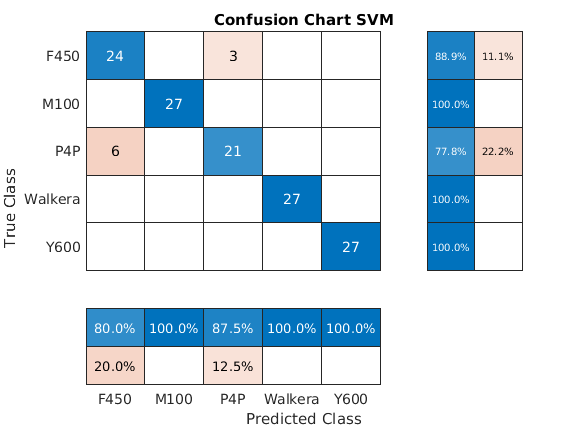

p=0.2*NumObj;

testF450 = Ffeat(p:2:p+2*(NumTestObj-1),:);
testM100 = Mfeat(p:2:p+2*(NumTestObj-1),:);
testP4P = Pfeat(p:2:p+2*(NumTestObj-1),:);
testWalkera = Wfeat(p:2:p+2*(NumTestObj-1),:);
testY600 = Yfeat(p:2:p+2*(NumTestObj-1),:);

trainF450=Ffeat; trainF450(p:2:p+2*(NumTestObj-1),:)=[];
trainM100=Mfeat; trainM100(p:2:p+2*(NumTestObj-1),:)=[];
trainP4P=Pfeat; trainP4P(p:2:p+2*(NumTestObj-1),:)=[];
trainWalkera=Wfeat; trainWalkera(p:2:p+2*(NumTestObj-1),:)=[];
trainY600=Yfeat; trainY600(p:2:p+2*(NumTestObj-1),:)=[];

RCSReturns=[trainF450;trainM100;trainP4P;trainWalkera;trainY600];
RCSTest=[testF450;testM100;testP4P;testWalkera;testY600];
% RCSReturns=array2table(RCSReturns);
% RCSTest=array2table(RCSTest);
% RCSReturns.Properties.VariableNames = {'Mean' 'Std' 'Max' 'Min' 'Emd1Mean' 'Emd1Std' 'Emd1Max' 'Emd1Min' 'Emd2Mean' 'Emd2Std' 'Emd2Max' 'Emd2Min' 'Emd3Mean' 'Emd3Std' 'Emd3Max' 'Emd3Min' 'Emd4Mean' 'Emd4Std' 'Emd4Max' 'Emd4Min'};
% RCSTest.Properties.VariableNames = {'Mean' 'Std' 'Max' 'Min' 'Emd1Mean' 'Emd1Std' 'Emd1Max' 'Emd1Min' 'Emd2Mean' 'Emd2Std' 'Emd2Max' 'Emd2Min' 'Emd3Mean' 'Emd3Std' 'Emd3Max' 'Emd3Min' 'Emd4Mean' 'Emd4Std' 'Emd4Max' 'Emd4Min'};

trainLabels = repelem(categorical({'F450','M100','P4P','Walkera','Y600'}),[NumTrainObj NumTrainObj NumTrainObj NumTrainObj NumTrainObj]).';
testLabels = repelem(categorical({'F450','M100','P4P','Walkera','Y600'}),[NumTestObj NumTestObj NumTestObj NumTestObj NumTestObj]).';
% trainLabels = cellstr(trainLabels);
% testLabels = cellstr(testLabels);
% t = templateSVM('Standardize',true,'KernelFunction','gaussian');
Mdl = fitcecoc(RCSReturns,trainLabels);
predictedLabelSVM = predict(Mdl,RCSTest);
figure;
ccDCNN = confusionchart(testLabels,predictedLabelSVM);
ccDCNN.Title = 'Confusion Chart SVM';
ccDCNN.ColumnSummary = 'column-normalized';
ccDCNN.RowSummary = 'row-normalized';

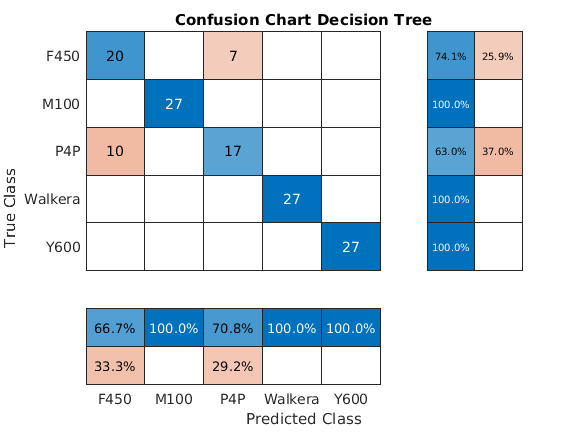


Md2 = fitctree(RCSReturns,trainLabels);
predictedLabelsTree = predict(Md2,RCSTest);
figure;
ccDCNN = confusionchart(testLabels,predictedLabelsTree);
ccDCNN.Title = 'Confusion Chart Decision Tree';
ccDCNN.ColumnSummary = 'column-normalized';
ccDCNN.RowSummary = 'row-normalized';

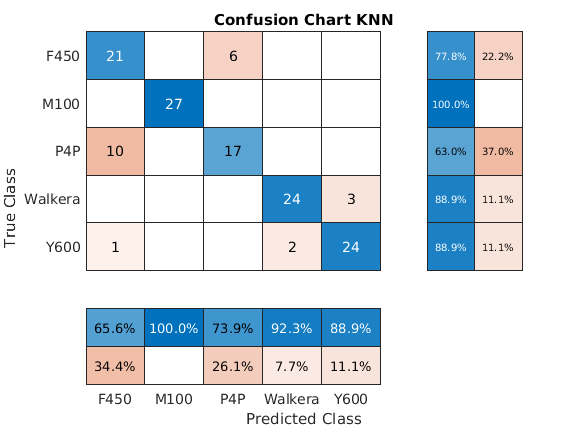


Md3 = fitcknn(RCSReturns,trainLabels);
predictedLabelsKNN = predict(Md3,RCSTest);
figure;
ccDCNN = confusionchart(testLabels,predictedLabelsKNN);
ccDCNN.Title = 'Confusion Chart KNN';
ccDCNN.ColumnSummary = 'column-normalized';
ccDCNN.RowSummary = 'row-normalized';


accuracySVM = sum(predictedLabelSVM == testLabels)*100/size(testLabels,1)

accuracySVM = 93.3333

accuracyTree = sum(predictedLabelsTree == testLabels)*100/size(testLabels,1)

accuracyTree = 87.4074

accuracyKNN = sum(predictedLabelsKNN == testLabels)*100/size(testLabels,1)

accuracyKNN = 83.7037

RCSReturnscell=num2cell(RCSReturns.',1).';
RCSTestcell=num2cell(RCSTest.',1).';

inputSize=20;
numHiddenUnits=100;
numClasses=5;
LSTMlayers = [ ...
    sequenceInputLayer(inputSize)
    bilstmLayer(numHiddenUnits,'OutputMode','last')
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];
options = trainingOptions('adam', ...
    'MaxEpochs',30, ...
    'MiniBatchSize', 50, ...
    'InitialLearnRate', 0.01, ...
    'GradientThreshold', 1, ...
    'plots','training-progress', ...
    'Verbose',false,'ExecutionEnvironment','cpu');

trainLabels = repelem(categorical({'F450','M100','P4P','Walkera', 'Y600'}),[NumTrainObj NumTrainObj NumTrainObj NumTrainObj NumTrainObj]);
trainLabels = trainLabels(:);
testLabels = repelem(categorical({'F450','M100','P4P','Walkera', 'Y600'}),[NumTestObj NumTestObj NumTestObj NumTestObj NumTestObj]);
testLabels = testLabels(:);
RNNnet = trainNetwork(RCSReturnscell,trainLabels,LSTMlayers,options);
predictedLabelsRNN = classify(RNNnet,RCSTestcell,'ExecutionEnvironment','cpu');
accuracyRNN = sum(predictedLabelsRNN == testLabels)*100/size(testLabels,1)

accuracyRNN = 88.8889

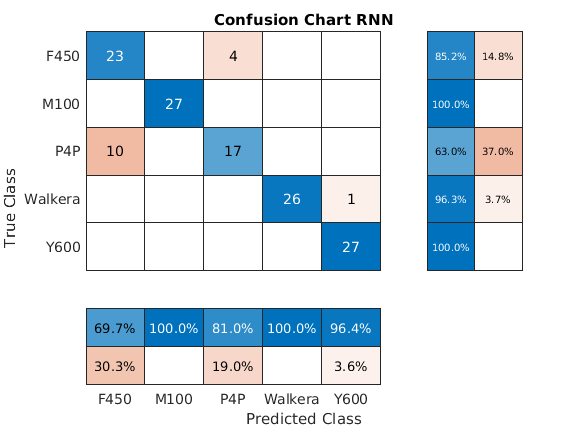

figure;
ccDCNN = confusionchart(testLabels,predictedLabelsRNN);
ccDCNN.Title = 'Confusion Chart RNN';
ccDCNN.ColumnSummary = 'column-normalized';
ccDCNN.RowSummary = 'row-normalized';